# 11주차 과제 — 주파수영역 설계

**제어시스템설계** · 충남대학교 자율운항시스템공학과

문제는 **세 개**입니다.

- **1. 몸풀기** (쉬움 · 수업 중 10분 · 30점) — Lead 의 $\alpha$ 를 손으로

- **2. 기본** (중간 · 40분 · 70점) — Lead 설계 5단계를 밟아 보기

- **3. 도전** (선택 · 가산점 10점) — Lag 로 같은 사양을 만족시키고 비교

**3번은 선택입니다.** 1번과 2번만 해도 만점입니다.

clc; close all;
s = tf('s');

## 1. 몸풀기 — Lead 의 $\alpha$ 를 손으로

**강의노트 2-1절을 그대로 보면 됩니다.**

Lead 보상기가 올릴 수 있는 최대 위상은 $\alpha$ 하나로 정해집니다.


$$\sin\phi_{max} = \frac{1-\alpha}{1+\alpha} \qquad \Rightarrow \qquad \alpha = \frac{1 - \sin\phi_{max}}{1 + \sin\phi_{max}}$$


그리고 그때 고주파 이득이 $1/\alpha$ 배가 됩니다. **이것이 대가입니다.**

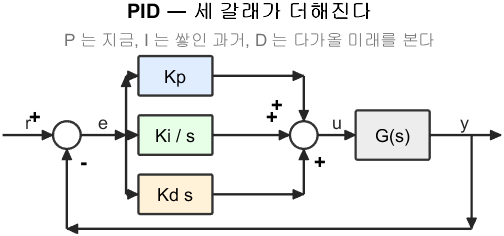

PID — 세 갈래가 더해진다

**그림 파일** `loop_pid.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_pid')`

## 1-1. 표 채우기

`TODO` 한 줄만 채우면 됩니다.

fprintf('     phi[도]    alpha     고주파 이득 배율\n');
fprintf('   ---------  --------  ------------------\n');
for ph = [20 35 50 65]
    al = NaN;
    % TODO : al = (1 - sind(ph))/(1 + sind(ph));  로 바꾸십시오
    if isnan(al)
        fprintf('   %9.0f  (아직 안 채움)\n', ph);
        continue
    end
    fprintf('   %9.0f  %8.4f  %18.1f\n', ph, al, 1/al);
end

## 1-2. 답할 것 (두 문장이면 됩니다)

- 위상을 $20^\circ$ 올릴 때와 $65^\circ$ 올릴 때, 고주파 이득 배율은 몇 배 차이입니까?

- 그래서 왜 "한 단으로 $60^\circ$ 이상은 무리" 라고 하는 것입니까?

**스스로 확인하는 법** — $\phi = 0$ 을 넣으면 $\alpha = 1$ 이 되어야 합니다. (보상기가 아무 일도 안 하는 경우입니다.)

## 2. 기본 — Lead 설계 5단계

**강의노트 1절과 2-2절을 그대로 보면 됩니다.**

강의노트에서 다룬 것과 **구조가 같고 숫자만 다른** 플랜트입니다.


$$G(s) = \frac{1}{s\,(s+2)}$$


사양

- 단위 램프 입력에 대한 정상상태 오차 $\le 0.02$

- 위상여유 $\ge 45^\circ$

G = 1/(s*(s+2));

## 2-1. 1단계 : 정상상태 사양으로 $K$ 정하기

타입 1 시스템이므로 램프 오차는 $1/K_v$ 입니다.


$$K_v = \lim_{s \to 0} s\,K\,G(s) = \frac{K}{2}$$


오차 $\le 0.02$ 이려면 $K_v \ge 50$, 즉 $K \ge 100$ 입니다.

K = NaN;    % TODO : 위 계산으로 나온 값을 넣으십시오

fprintf('\n=== 2-1단계 : K 정하기 ===\n');
if isnan(K)
    fprintf('  K 를 아직 안 채웠습니다.\n');
else
    fprintf('  K = %.0f\n', K);
    fprintf('  확인 : Kv = %.2f, 램프 오차 = %.4f  (요구 0.02 이하)\n', ...
            dcgain(s*K*G), 1/dcgain(s*K*G));
end

## 2-2. 2단계 : 현재 위상여유

코드는 다 되어 있습니다.

if ~isnan(K)
    [gm0, pm0, ~, wcp0] = margin(K*G);
    ii0 = stepinfo(feedback(K*G, 1));
    fprintf('\n=== 2-2단계 : 현재 상태 ===\n');
    fprintf('  위상여유 %.2f 도  (요구 45 이상)\n', pm0);
    fprintf('  교차주파수 %.3f rad s^-1\n', wcp0);
    fprintf('  오버슈트 %.1f %%, 정착시간 %.2f s\n', ii0.Overshoot, ii0.SettlingTime);
end

## 2-3. 3~5단계 : 보상기 설계

손으로 계산해 본 뒤 `lead_design` 결과와 비교하십시오.

PM_req = 45;
extra  = 5;

phi   = NaN;    % TODO : PM_req - pm0 + extra
alpha = NaN;    % TODO : (1 - sind(phi))/(1 + sind(phi))

fprintf('\n=== 2-3단계 : 손계산 ===\n');
if isnan(phi) || isnan(alpha)
    fprintf('  phi 또는 alpha 를 아직 안 채웠습니다.\n');
else
    fprintf('  모자란 각 phi = %.2f 도\n', phi);
    fprintf('  alpha = %.4f  (고주파 이득 %.1f 배)\n', alpha, 1/alpha);
end

if ~isnan(K)
    [D, info] = lead_design(K, G, PM_req, extra);
    fprintf('\n  lead_design 의 결과\n');
    fprintf('    phi = %.2f 도, alpha = %.4f\n', info.phi, info.alpha);
    fprintf('    wm = %.3f rad s^-1, T = %.4f\n', info.wm, info.T);
    fprintf('    영점 s = %.3f, 극점 s = %.3f\n', info.zero, info.pole);
    fprintf('    위상여유 %.2f -> %.2f 도\n', info.PM_before, info.PM_after);
end

## 2-4. 5단계 : 검증

코드는 다 되어 있습니다. **제어입력을 반드시 보십시오.**

if ~isnan(K)
    t = (0:0.002:4)';
    w = logspace(-1, 3, 500);

    figure;
    subplot(2,2,1);
    semilogx(w, 20*log10(squeeze(abs(freqresp(K*G, w)))), 'LineWidth', 2); hold on; grid on;
    semilogx(w, 20*log10(squeeze(abs(freqresp(D*G, w)))), 'LineWidth', 2);
    yline(0,'k--'); ylabel('크기 [dB]'); ylim([-60 60]);
    legend('보상 전','Lead','Location','southwest');
    title('크기');

    subplot(2,2,2);
    plot(t, step(feedback(K*G,1), t), 'LineWidth', 2); hold on; grid on;
    plot(t, step(feedback(D*G,1), t), 'LineWidth', 2);
    yline(1,'k--'); xlabel('시간 [s]'); ylabel('출력');
    legend('보상 전','Lead','Location','southeast');
    title('계단응답');

    subplot(2,2,3);
    semilogx(w, unwrap(squeeze(angle(freqresp(K*G, w))))*180/pi, 'LineWidth', 2);
    hold on; grid on;
    semilogx(w, unwrap(squeeze(angle(freqresp(D*G, w))))*180/pi, 'LineWidth', 2);
    yline(-180,'k--'); xlabel('주파수 [rad s^{-1}]'); ylabel('위상 [도]');
    title('위상');

    subplot(2,2,4);
    ub = step(feedback(K, G), t);
    ua = step(feedback(D, G), t);
    plot(t, ub, 'LineWidth', 2); hold on; grid on;
    plot(t, ua, 'LineWidth', 2);
    xlabel('시간 [s]'); ylabel('제어입력 u');
    legend(sprintf('보상 전 (최대 %.0f)', max(abs(ub))), ...
           sprintf('Lead (최대 %.0f)', max(abs(ua))), 'Location','northeast');
    title('제어입력');

    jb = stepinfo(feedback(K*G,1));
    ja = stepinfo(feedback(D*G,1));
    fprintf('\n=== 2-4단계 : 검증 ===\n');
    fprintf('              위상여유[도]   오버슈트[%%]   정착시간[s]   최대 |u|\n');
    fprintf('   ---------  ------------  ------------  -----------  ---------\n');
    fprintf('   보상 전    %12.2f  %12.2f  %11.3f  %9.1f\n', ...
            info.PM_before, jb.Overshoot, jb.SettlingTime, max(abs(ub)));
    fprintf('   Lead 적용  %12.2f  %12.2f  %11.3f  %9.1f\n', ...
            info.PM_after, ja.Overshoot, ja.SettlingTime, max(abs(ua)));
end

## 2-5. 답할 것 (세 문장이면 됩니다)

- 위상여유 요구를 만족했습니까?

- Lead 를 넣고 나서 정상상태 오차는 어떻게 되었습니까? 왜 그렇습니까?

- 최대 제어입력이 몇 배로 커졌습니까? 그 값이 $1/\alpha$ 와 어떤 관계입니까?

## 3. 도전 (선택) — Lag 로 같은 사양을

**강의노트 3-2절을 보면 됩니다.**

같은 플랜트, 같은 사양을 **Lag** 로 만족시켜 보십시오. 그리고 Lead 와 무엇이 다른지 비교하십시오.

if ~isnan(K)
    [Dg, ig] = lag_design(K, G, PM_req, 8);

    fprintf('\n=== 3. Lag 로 설계 ===\n');
    fprintf('  새 교차주파수 %.3f rad s^-1, beta = %.2f\n', ig.wc_new, ig.beta);
    fprintf('  위상여유 %.2f -> %.2f 도\n\n', ig.PM_before, ig.PM_after);

    fprintf('              위상여유[도]   대역폭[rad s^-1]   정착시간[s]   최대 |u|\n');
    fprintf('   ---------  ------------  -----------------  -----------  ---------\n');
    cases = { '보상 전', tf(K); 'Lead', D; 'Lag', Dg };
    for i = 1:3
        Ci = cases{i,2};
        [~, pmi] = margin(Ci*G);
        Ti = feedback(Ci*G, 1);
        ji = stepinfo(Ti);
        ui = step(feedback(Ci, G), t);
        fprintf('   %-9s  %12.2f  %17.3f  %11.2f  %9.1f\n', ...
                cases{i,1}, pmi, bandwidth(Ti), ji.SettlingTime, max(abs(ui)));
    end

    figure;
    hold on; grid on;
    for i = 1:3
        plot(t, step(feedback(cases{i,2}*G,1), t), 'LineWidth', 2, 'DisplayName', cases{i,1});
    end
    yline(1,'k--','HandleVisibility','off');
    xlabel('시간 [s]'); ylabel('출력'); legend('Location','southeast');
    title('같은 위상여유를 Lead 와 Lag 로');
end

## 3-1. 답할 것 (두 문장이면 됩니다)

- 같은 위상여유인데 정착시간과 제어입력은 어떻게 다릅니까?

- 이 플랜트를 구동하는 모터가 아주 약하다면 어느 쪽을 고르겠습니까? 왜?

## 4. 제출과 채점

제출할 것

- 이 파일의 `TODO` 를 채운 `.m`

- 그림 (2-4절의 네 칸 그림)

- 답할 것에 대한 짧은 서술 (한 문단이면 충분합니다)

채점 기준

- **1번 30점** — 표가 채워져 있고 두 질문에 답했는가

- **2번 70점** — 5단계를 밟아 사양을 만족했고 제어입력을 확인했는가

- **3번 +10점** — Lag 로도 설계하고 Lead 와 비교했는가 (선택)

감점 항목 (세 개뿐입니다)

- 1단계(정상상태로 $K$ 정하기)를 건너뛴 경우

- 제어입력을 확인하지 않은 경우

- 그림에 축 이름이나 단위가 없는 경우